# Visualisation of four limit cycles (adaptation)

## 1) Reproduction of 4 limit cycle example by Kuznetsov et al.

Resolution of a proposed case with an implementation of Runge-Kutta 4.

% Initial conditions (t=0)
global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.7;c2=0.4;al2=-437.5;bt2=0.003;

h=0.01;
tf=30;
N=ceil(tf/h);

t=zeros(1,N+1);
x=zeros(1,N+1);
y=zeros(1,N+1);

t(1)=0;
x(1)=1;
y(1)=0;

[x,y] = RK4(t,x,y);

## 2) Grid in (x,y) plane

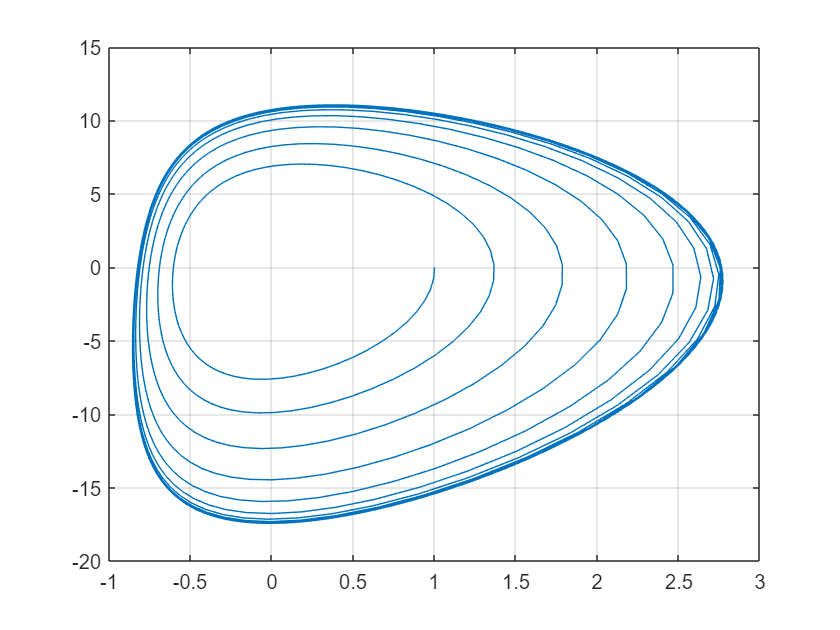

plot(x,y)
grid on
hold on

% t(1)=0;
% x(1)=3;
% y(1)=0;
% 
% [x,y] = RK4(t,x,y);
% 
% plot(x,y)
% grid on
hold off

## 3) Time integration

Find cycle intercepts with x-axis.

%parallelisable

p=[];
for i=1:N-1
    if (y(i)*y(i+1))<=0
        p(end+1)=i;
    end
end

Calculate difference between values of x intercepts that are non-consecutive, i.e. on the same "phase" of the cycle.

%parallelisable

xdif=zeros(1,size(p,2)-1);
x2=zeros(1,size(p,2)-1);
M=size(p,2)-2;
iter = 1;

 for i=1:2:M
    xdif(iter)=x(p(i+2))-x(p(i));
    x2(iter)=x(p(i));
    iter=iter+1;
 end

Plot x(t) vs x(t+2)-x(t)

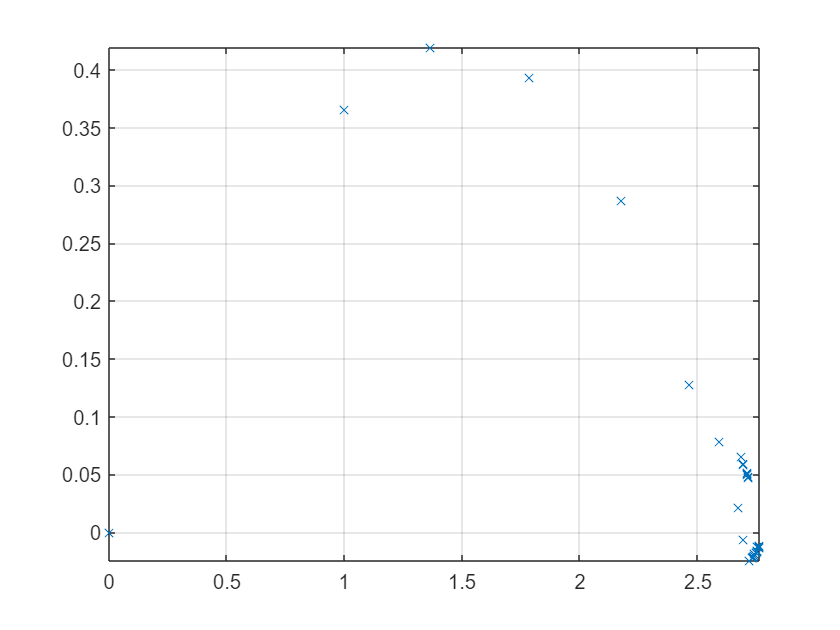

 plot(x2,xdif,"x")
 grid on

Integrate for positive and negative t

%code here

## Adaptation of Kuznetsov et al.

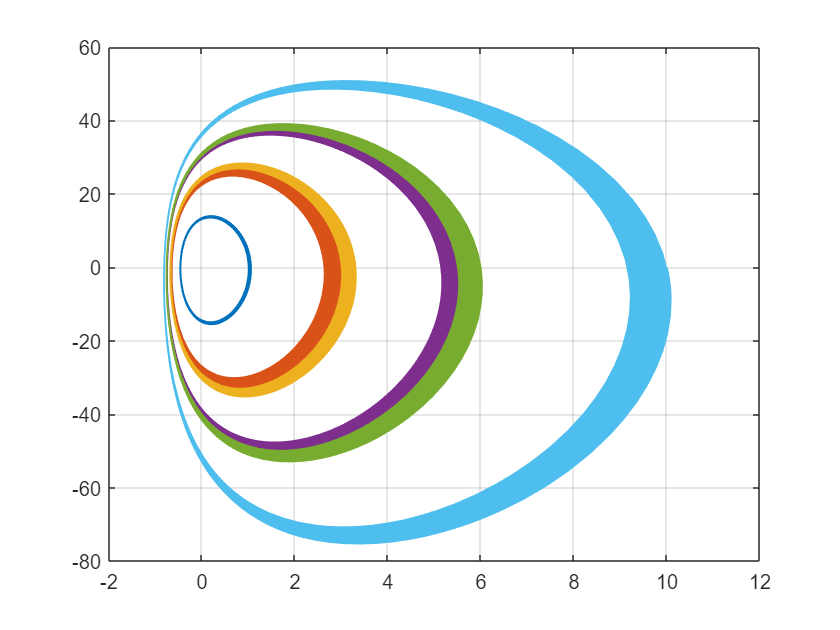

clear all; syms x
global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.7;c2=0.4;al2=-437.5;bt2=0.003;
x0_1=1; x0_2=3; x0_3=5.5; x0_4=10;
acc=0.00001; y0_1=-2000; y0_2=-4000; 
len1=40*pi; len2=70*pi; len3=-30*pi; len4=-30*pi; len5=25*pi; len6=15*pi; len7=-1*pi; len8=-1*pi;

RelTol=acc; AbsTol=acc; InitialStep=acc;
options=odeset('RelTol', RelTol ,'AbsTol', AbsTol, 'InitialStep', InitialStep, 'NormControl','on');


x0=x0_1 ; y0=0;[T, XY]= ode45(@fQsys, [0 len1], [x0 y0], options);
plot(XY(: ,1), XY(: ,2));
hold on; grid on;
x0=x0_2 ; y0=0;[T, XY]= ode45(@fQsys, [0 len2], [x0 y0], options);
plot(XY(: ,1), XY(: ,2));
hold on; grid on;

x0=x0_2 ; y0=0;[ T, XY ]= ode45(@fQsys ,[0 len3 ] ,[ x0 y0 ], options);
plot(XY(: ,1), XY(: ,2));
hold on; grid on;
x0=x0_3 ; y0=0;[ T, XY ]= ode45(@fQsys ,[0 len4 ] ,[ x0 y0 ], options);
plot(XY(: ,1), XY(: ,2));
hold on; grid on;

x0=x0_3 ; y0=0;[T, XY]= ode45(@fQsys ,[0 len5] ,[x0 y0], options);
plot(XY(: ,1), XY(: ,2));
hold on; grid on;
x0=x0_4 ; y0=0;[T, XY]= ode45(@fQsys ,[0 len6] ,[x0 y0], options);
plot(XY(: ,1), XY(: ,2));
hold on; grid on;

## Result comparison

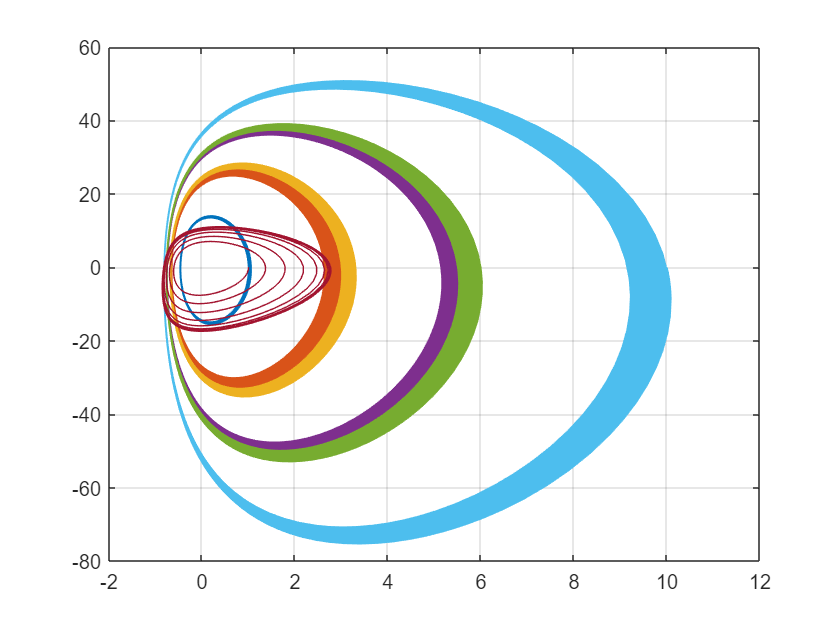

h=0.01;
tf=30;
N=ceil(tf/h);

t=zeros(1,N+1);
x=zeros(1,N+1);
y=zeros(1,N+1);

t(1)=0;
x(1)=1;
y(1)=0;

[x,y] = RK4(t,x,y);
plot(x,y); grid on; hold off

## Functions

function dz=fQsys(t, z)
    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    dz=zeros(2,1); % z=(z(1),z(2))=(x,y)
    
    dz(1)=(a1 * z(1)^2+ b1 * z(1)* z(2)+ c1 * z(2)^2+ al1 * z(1)+ bt1 * z(2));
    dz(2)=(a2 * z(1)^2+ b2 * z(1)* z(2)+ c2 * z(2)^2+ al2 * z(1)+ bt2 * z(2));
end

function [x,y] = RK4(t,x,y)

    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    
    % ODE
    dxdt=@(t,x,y) a1*x^2 + b1*x*y + c1*y^2 + al1*x + bt1*y;
    dydt=@(t,x,y) a2*x^2 + b2*x*y + c2*y^2 + al2*x + bt2*y;
    
    % Step size
    h=0.01;
    tf=30;
    N=ceil(tf/h);
    
    % Runge-Kutta 4
    
        for i=1:N
            t(i+1)=t(i)+h;
        
            k1x=dxdt(t(i), x(i), y(i));
            k1y=dydt(t(i), x(i), y(i));
        
            k2x=dxdt(t(i)+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
            k2y=dxdt(t(i)+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
        
            k3x=dxdt(t(i)+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
            k3y=dxdt(t(i)+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
        
            k4x=dxdt(t(i)+h, x(i)+h*k3x, y(i)+h*k3y);
            k4y=dxdt(t(i)+h, x(i)+h*k3x, y(i)+h*k3y);
        
            x(i+1)=x(i) + h/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + h/6*(k1y+2*k2y+2*k3y+k4y);
        end
end